## AAE 440 PS10 Problem 3

clear all; close all; clc;
fdir = 'C:\Users\Tomo\Desktop\studies\2020-Spring\AAE440\MATLAB\outputs\HW10';
set(groot, 'defaulttextinterpreter','latex');  
set(groot, 'defaultAxesTickLabelInterpreter','latex');  
set(groot, 'defaultLegendInterpreter','latex');

### (b)

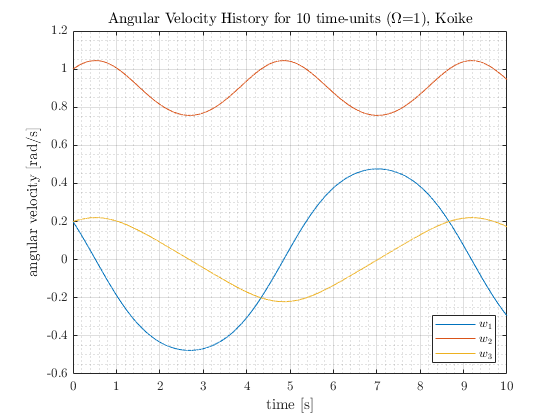

% Defining System Properties
I = [400 100 800];          % moment of inertia [kg-m2]
Omega = 1;
w0 = Omega*[0.2 1 0.2];     % initial angular velocity [rad/s]
t_span = 0:0.001:10;       % 10 time-units [s]

% Numerical Integration
opt = odeset('RelTol', 1e-13, 'AbsTol', 1e-13);
[t, data] = ode45(@(t,w) Tfree_unsymm_EOM(t,w,I),t_span,w0,opt);

% Assign variables from the output of the numerical integration 
w1 = data(:,1);
w2 = data(:,2);
w3 = data(:,3);

% Plot the angular velocities 
fig1 = figure("Renderer","painters");
    plot(t,w1)
    title({'Angular Velocity History for 10 time-units ($\Omega$=1), Koike'})
    xlabel('time [s]')
    ylabel('angular velocity [rad/s]')
    hold on;
    plot(t,w2); plot(t,w3); hold off;
    grid on; grid minor; box on;
    legend('$w_1$','$w_2$','$w_3$',"Location",'southeast')
saveas(fig1,fullfile(fdir,'P3-b_angVel.png'));


% Find amplitude for each angular velocity 
amp_w1 = (max(w1)-min(w1))/2

amp_w1 = 0.4761

amp_w2 = (max(w2)-min(w2))/2

amp_w2 = 0.1438

amp_w3 = (max(w3)-min(w3))/2

amp_w3 = 0.2204

#### (c)

% Angle between omegaNB and b2 hat
b2_hat = [0 1 0];
w0_hat = w0/norm(w0)

w0_hat =     0.1925    0.9623    0.1925


zeta = acosd(dot(w0_hat,b2_hat))

zeta = 15.7932

% Angle between H_NB and b2 hat
H_NB = I.*w0

H_NB =     80   100   160


H_NB_hat = H_NB/norm(H_NB)

H_NB_hat =     0.3904    0.4880    0.7807


psi = acosd(dot(H_NB_hat,b2_hat))

psi = 60.7941

#### (d)

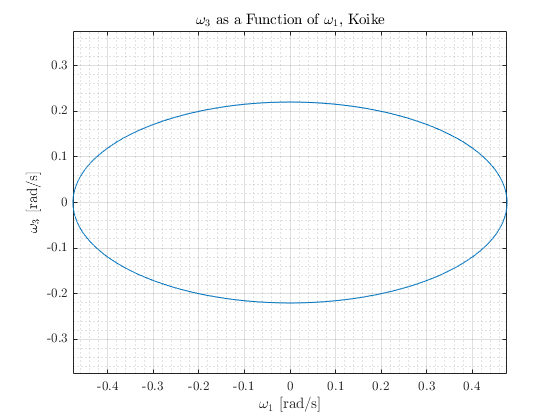

% Plotting w3 as a function w1
fig2 = figure("Renderer","painters");
    plot(w1,w3)
    title({'$\omega_3$ as a Function of $\omega_1$, Koike'})
    xlabel('$\omega_1$ [rad/s]'); ylabel('$\omega_3$ [rad/s]')
    grid on; grid minor; box on; axis equal;
saveas(fig2,fullfile(fdir,'P3-d_w1_vs_w3.png'));

#### (f)

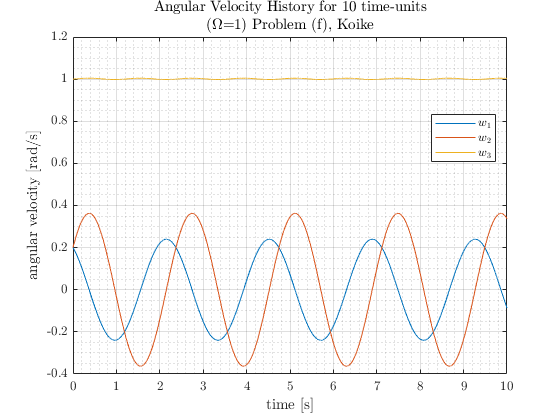

w0 = Omega*[0.2 0.2 1];     % initial angular velocity [rad/s]

% Numerical Integration
opt = odeset('RelTol', 1e-13, 'AbsTol', 1e-13);
[t, data] = ode45(@(t,w) Tfree_unsymm_EOM(t,w,I),t_span,w0,opt);

% Assign variables from the output of the numerical integration 
w1 = data(:,1);
w2 = data(:,2);
w3 = data(:,3);

% Plot the angular velocities 
fig3 = figure("Renderer","painters");
    plot(t,w1)
    title({'Angular Velocity History for 10 time-units', '($\Omega$=1) Problem (f), Koike'})
    xlabel('time [s]')
    ylabel('angular velocity [rad/s]')
    hold on;
    plot(t,w2); plot(t,w3); hold off;
    grid on; grid minor; box on;
    legend('$w_1$','$w_2$','$w_3$',"Location",'best')
saveas(fig3,fullfile(fdir,'P3-e_angVel.png'));


% Angle between omegaNB and b2 hat
b2_hat = [0 1 0];
w0_hat = w0/norm(w0)

w0_hat =     0.1925    0.1925    0.9623


zeta = acosd(dot(w0_hat,b2_hat))

zeta = 78.9042

acosd(dot(w0_hat,[1 0 0]))

ans = 78.9042

acosd(dot(w0_hat,[0 0 1]))

ans = 15.7932


% Angle between H_NB and b2 hat
H_NB = I.*w0

H_NB =     80    20   800


H_NB_hat = H_NB/norm(H_NB)

H_NB_hat =     0.0995    0.0249    0.9947


psi = acosd(dot(H_NB_hat,b2_hat))

psi = 88.5750

acosd(dot(H_NB_hat,[1 0 0]))

ans = 84.2912

acosd(dot(H_NB_hat,[0 0 1]))

ans = 5.8851